clear variables
clc
clf

# **OD Data**

figure()
hold on

load Soro_stuff.mat %30C
plot(Cap_times(1:end-1),Cap_ave(1:end-1),'go--','LineWidth',1.5)
errorbar(Cap_times(1:end-1),Cap_ave(1:end-1),Cap_std(1:end-1),'k','LineStyle','none');

load Cap_Dim_Rerun_stuff.mat %30C
plot(Cap_times(1:end-1),Cap_ave(1:end-1),'go-','LineWidth',1.5)
errorbar(Cap_times(1:end-1),Cap_ave(1:end-1),Cap_std(1:end-1),'k','LineStyle','none');

load Cap_Soro_Rerun_stuff.mat %37C
plot(Cap_times,Cap_ave,'ko--','LineWidth',1.5)
errorbar(Cap_times,Cap_ave,Cap_std,'k','LineStyle','none');

load Dim_stuff.mat %37C
plot(Cap_times,Cap_ave,'ko-','LineWidth',1.5)
errorbar(Cap_times,Cap_ave,Cap_std,'k','LineStyle','none');

hold off
grid on
xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold')
ylabel('OD_{750}','FontSize',18,'FontWeight','bold')
lgd = legend('Soro(30)','','Dim(30)','','Soro(37)','','Dim(37)','','location','northwest')

lgd =   Legend (Soro(30), Dim(30), Soro(37), Dim(37)) with properties:

         String: {'Soro(30)'  'Dim(30)'  'Soro(37)'  'Dim(37)'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.1494 0.7353 0.1750 0.1655]
          Units: 'normalized'

  Show all properties


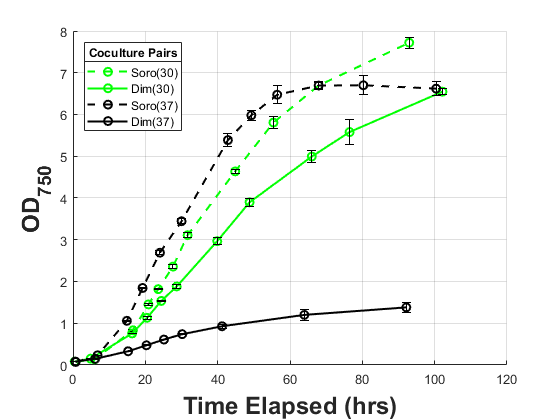

title(lgd,'Coculture Pairs')

# **Biomass Measurements w/ MAKIMA fits**

figure()
hold on

load SoroCap_biomass30.mat %30C
xq1 = linspace(Cap_times(3),Cap_times(end-1),200);
yq1 = makima(Cap_times([3:end-1]),C_w_ave-0.345,xq1);
plot(Cap_times([3:end-1]),C_w_ave-0.345,'go',xq1,yq1,'g--','LineWidth',1.5);
errorbar(Cap_times([3:end-1]),C_w_ave-0.345,C_w_std,'k','LineStyle','none');

load Cap_Dim_biomass.mat %30C
xq2 = linspace(Cap_times(2),Cap_times(end-1),200);
yq2 = makima(Cap_times([2:end-1]),C_w_ave(1:end-1),xq2);
plot(Cap_times(2:end-1),C_w_ave(1:end-1),'go',xq2,yq2,'g-','LineWidth',1.5)
errorbar(Cap_times(2:end-1),C_w_ave(1:end-1),C_w_std(1:end-1),'k','LineStyle','none');

load Cap_Soro_biomass.mat %37C
xq3 = linspace(Cap_times(2),Cap_times(end),200);
yq3 = makima(Cap_times([2:7,9:end]),C_w_ave-0.345,xq3);
plot(Cap_times([2:7,9:end]),C_w_ave-0.345,'ko',xq3,yq3,'k--','LineWidth',1.5);
errorbar(Cap_times([2:7,9:end]),C_w_ave-0.345,C_w_std,'k','LineStyle','none');

load DimCap_biomass.mat %37C
xq4 = linspace(Cap_times(5),Cap_times(end),200);
yq4 = makima(Cap_times([5:end]),C_w_ave-0.345,xq4);
plot(Cap_times(5:end),C_w_ave-0.345,'ko',xq4,yq4,'k-','LineWidth',1.5);
errorbar(Cap_times(5:end),C_w_ave-0.345,C_w_std,'k','LineStyle','none');

hold off
grid on
xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold')
ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold')
lgd = legend('','Soro(30)','','','Dim(30)','','','Soro(37)','','','Dim(37)','','location','northwest')

lgd =   Legend (Soro(30), Dim(30), Soro(37), Dim(37)) with properties:

         String: {'Soro(30)'  'Dim(30)'  'Soro(37)'  'Dim(37)'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.1494 0.7353 0.1750 0.1655]
          Units: 'normalized'

  Show all properties


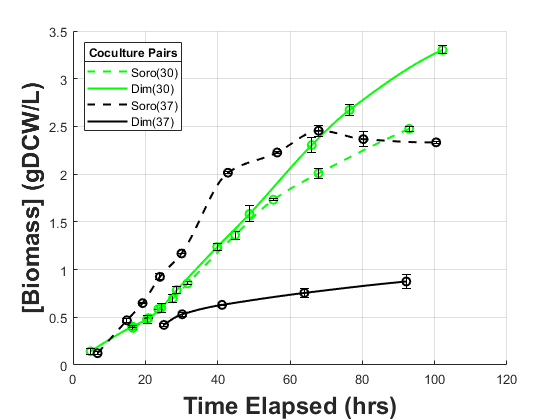

title(lgd,'Coculture Pairs')

# **Without MAKIMA fits**

figure()
hold on

load SoroCap_biomass30.mat %30C
plot(Cap_times([3:end-1]),C_w_ave-0.345,'go--')
errorbar(Cap_times([3:end-1]),C_w_ave-0.345,C_w_std,'k','LineStyle','none');

load Cap_Dim_biomass.mat %30C
plot(Cap_times(2:end),C_w_ave,'go-')
errorbar(Cap_times(2:end),C_w_ave,C_w_std,'k','LineStyle','none');

load Cap_Soro_biomass.mat %37C
plot(Cap_times([2:7,9:end]),C_w_ave-0.345,'ko--')
errorbar(Cap_times([2:7,9:end]),C_w_ave-0.345,C_w_std,'k','LineStyle','none');

load DimCap_biomass.mat %37C
plot(Cap_times(5:end),C_w_ave-0.345,'ko-')
errorbar(Cap_times(5:end),C_w_ave-0.345,C_w_std,'k','LineStyle','none');

hold off
grid on
xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold')
ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold')
lgd = legend('Soro(30)','','Dim(30)','','Soro(37)','','Dim(37)','','location','northwest')

lgd =   Legend (Soro(30), Dim(30), Soro(37), Dim(37)) with properties:

         String: {'Soro(30)'  'Dim(30)'  'Soro(37)'  'Dim(37)'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.1494 0.7353 0.1750 0.1655]
          Units: 'normalized'

  Show all properties


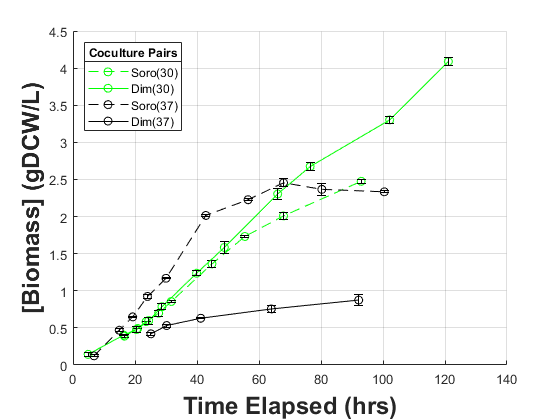

title(lgd,'Coculture Pairs')